# Multi-link pendulum system: Simscape modeling

Input system parameters:

%% PENDULUM PARAMETERS %%
init_angle=45   % Initial angle from vertical (degrees)

init_angle = 45

n_links=4       % Number of links 

n_links = 4


L=60;           % Total length of pendulum (cm)
W=2;            % Width of links (cm)
H=2;            % Depth of links (cm)
damping=0.005;     % Damping factor at joints (N*m/(deg/s))
spring=0.01;    % Torsional spring constant (N*m/deg)

%% MEASUREMENT PARAMETERS %%
coord_noise_std=0;
angle_noise_std=0;

%% SIMULATION PARAMETERS %%
sim_steps = 600;
dt = 0.01;
t = [0:dt:dt*(sim_steps-1)]';
n_sims = 30;
torque_gain = 0.05;
total_sim_time = sim_steps*dt*n_sims

total_sim_time = 0.1000

%rand_torque = normrnd(0, torque_gain, sim_steps * n_sims, 1);

% random walk torque
%rand_torque = cumsum(rand_torque) ./ sqrt(1:sim_steps * n_sims)';

% random walk but with decay instead of big division
rand_torque = zeros(sim_steps*n_sims, 1);
for i = 2:sim_steps*n_sims
    rand_torque(i) = normrnd(rand_torque(i-1), torque_gain);
    rand_torque(i) = 0.98 * rand_torque(i);
end

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','through');
end

data_len = (sim_steps-1)*n_sims

data_len = 9


in_torque = zeros(data_len, 1);

in_ex = zeros(data_len, 1);
in_ez = zeros(data_len, 1);
in_er = zeros(data_len, 1);
in_phi = zeros(data_len, 1);

out_ex = zeros(data_len, 1);
out_ez = zeros(data_len, 1);
out_er = zeros(data_len, 1);
out_phi = zeros(data_len, 1);

in_edx = zeros(data_len, 1);
in_edz = zeros(data_len, 1);
in_edr = zeros(data_len, 1);
in_dphi = zeros(data_len, 1);
in_dr = zeros(data_len, 1);
in_dtheta = zeros(data_len, 1);

out_edx = zeros(data_len, 1);
out_edz = zeros(data_len, 1);
out_edr = zeros(data_len, 1);
out_dphi = zeros(data_len, 1);
out_dr = zeros(data_len, 1);
out_dtheta = zeros(data_len, 1);

% Simulate model
for sim_n=1:n_sims
    log_indices = (sim_n-1)*(sim_steps-1)+1:sim_n*(sim_steps-1);
    torque_indices = (sim_n-1)*sim_steps+1:sim_n*sim_steps;
    torque = timeseries(rand_torque(torque_indices), t);

    % init_angle = min(max(normrnd(0, 90), -180), 180);

    simout = sim("pendulum_system.slx", t);
    
    % This is quite long but hopefully clear what is being set up

    phi = simout.pendulum_angle-pi;    % 0 at top, positive anticlockwise

    ex = simout.end_x;  % Centre 0, positive right

    ez = simout.end_z;  % Centre 0, positive upwards

    er = simout.end_rotation;

    in_torque(log_indices) = rand_torque(torque_indices(1:length(torque_indices)-1));

    in_phi(log_indices) = wrapTo2Pi(phi(1:sim_steps-1)) - pi;   % 0 at top, positive anticlockwise
    in_ex(log_indices) = ex(1:sim_steps-1);
    in_ez(log_indices) = ez(1:sim_steps-1);
    in_er(log_indices) = er(1:sim_steps-1);

    out_phi(log_indices) = wrapTo2Pi(phi(2:sim_steps)) - pi;    % 0 at top, positive anticlockwise
    out_ex(log_indices) = ex(2:sim_steps);
    out_ez(log_indices) = ez(2:sim_steps);
    out_er(log_indices) = er(2:sim_steps);

    r = sqrt(ex.^2 + ez.^2);
    theta = atan2(ez, ex) - pi/2;   % 0 at top, positive anticlockwise

    dphi = gradient(phi);
    dex = gradient(ex);
    dez = gradient(ez);
    der = gradient(er);
    dr = gradient(r);
    dtheta = gradient(theta);

    in_dphi(log_indices) = dphi(1:sim_steps-1);
    in_edx(log_indices) = dex(1:sim_steps-1);
    in_edz(log_indices) = dez(1:sim_steps-1);
    in_edr(log_indices) = der(1:sim_steps-1);
    in_dr(log_indices) = dr(1:sim_steps-1);
    in_dtheta(log_indices) = dtheta(1:sim_steps-1);

    out_dphi(log_indices) = dphi(2:sim_steps);
    out_edx(log_indices) = dex(2:sim_steps);
    out_edz(log_indices) = dez(2:sim_steps);
    out_edr(log_indices) = der(2:sim_steps);
    out_dr(log_indices) = dr(2:sim_steps);
    out_dtheta(log_indices) = dtheta(2:sim_steps);
end

% New coordinate scheme
in_r = sqrt(in_ex.^2 + in_ez.^2);
in_theta = atan2(in_ez, in_ex) - pi/2;  % 0 at top, postitive anticlockwise
out_r = sqrt(out_ex.^2 + out_ez.^2);    
out_theta = atan2(out_ez, out_ex);  % 0 at top, postitive anticlockwise

nn_input = cat(2, in_phi, in_r, in_theta, in_dphi, in_dr, in_dtheta, in_torque);
nn_targets = cat(2, out_phi, out_r, out_theta, out_dphi, out_dr, out_dtheta);

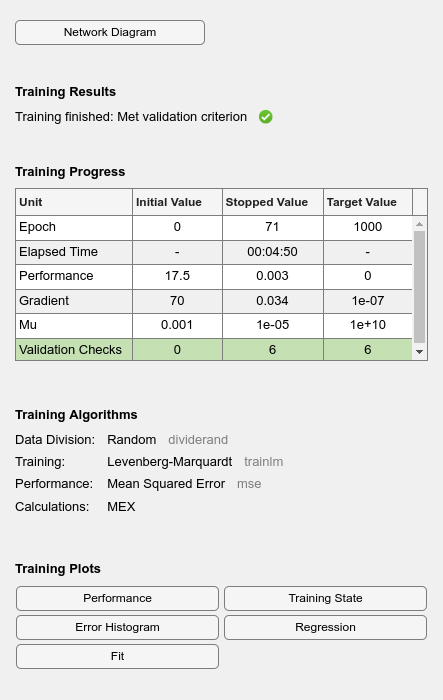

performance = 0.0095

trainPerformance = 0.0060

valPerformance = 0.0189

testPerformance = 0.0161

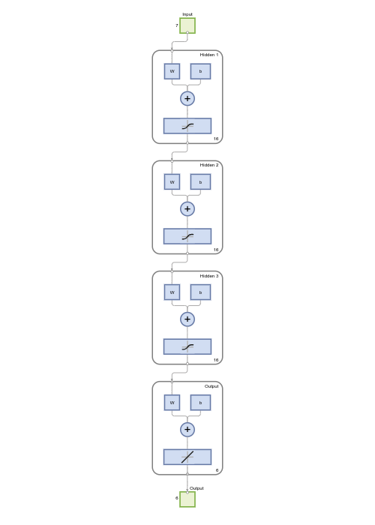

 
MATLAB function generated: dynamics.m
To view generated function code: edit dynamics
For examples of using function: help dynamics
 


% Train the network, name it dynamics
% dynamics_train
dynamics_train